clc;
clear;
close all hidden;


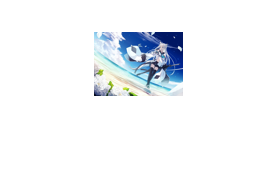

I=imread('kawakaze.jpg');
I=imresize(I,[64,NaN]);
imshow(I);

X=I(:,:,1);
Y=I(:,:,2);
Z=I(:,:,3);

Color=[X(:),Y(:),Z(:)];

[Color_cen,MS_model] = clusteringMeanShift(double(Color));
Color_cen=uint8(Color_cen);


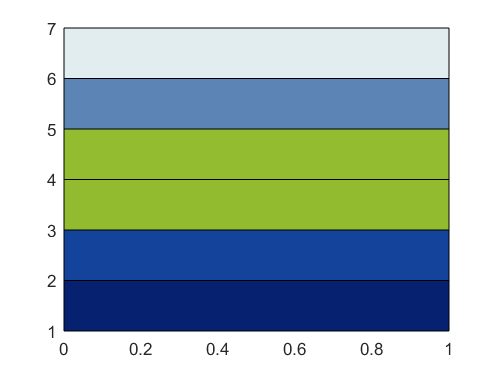

close all hidden;
[~,idx]=sort(sum(Color_cen,2));
Color_cen=Color_cen(idx,:);

cen_num=size(Color_cen,1);
hold on;
for cen_idx=1:cen_num
    X=[0,1,1,0];
    Y=[0,0,1,1]+cen_idx;
    fill(X,Y,Color_cen(cen_idx,:));
end
hold off;

Color=[6,33,112;225,237,239;148,188,48];
my_color_map=[
    [linspace(Color(1,1),Color(2,1),101),linspace(Color(2,1),Color(3,1),101)];
    [linspace(Color(1,2),Color(2,2),101),linspace(Color(2,2),Color(3,2),101)];
    [linspace(Color(1,3),Color(2,3),101),linspace(Color(2,3),Color(3,3),101)];]';
my_color_map=uint8(my_color_map);

Color=[92,132,181;225,237,239;148,188,48];
my_color_map_light=[
    [linspace(Color(1,1),Color(2,1),101),linspace(Color(2,1),Color(3,1),101)];
    [linspace(Color(1,2),Color(2,2),101),linspace(Color(2,2),Color(3,2),101)];
    [linspace(Color(1,3),Color(2,3),101),linspace(Color(2,3),Color(3,3),101)];]';
my_color_map_light=uint8(my_color_map_light);

save('color','my_color_map','my_color_map_light')